clear;
m1=-1;
m2=1;
N=1000;

var1=0.25;
var2=0.49;
var3=1.00;

x11=sqrt(var1)*randn(1,N)+m1;
x12=sqrt(var1)*randn(1,N)+m2;
x1=[x11 x12];

x21=sqrt(var2)*randn(1,N)+m1;
x22=sqrt(var2)*randn(1,N)+m2;
x2=[x21 x22];

x31=sqrt(var3)*randn(1,N)+m1;
x32=sqrt(var3)*randn(1,N)+m2;
x3=[x31 x32];

Oppgave 1

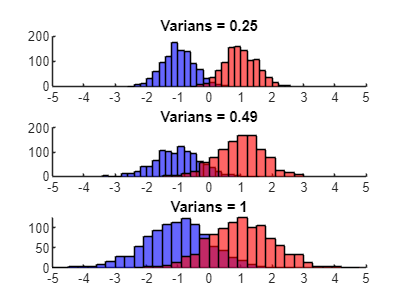

figure;
subplot(3,1,1);
hold on
histogram(x11,'FaceColor','b');
histogram(x12,'FaceColor','r');
xlim([-5 5]); xticks(-5:1:5);
title("Varians = "+var1);

subplot(3,1,2);
hold on
histogram(x21,'FaceColor','b');
histogram(x22,'FaceColor','r');
xlim([-5 5]); xticks(-5:1:5);
title("Varians = "+var2);

subplot(3,1,3);
hold on
histogram(x31,'FaceColor','b');
histogram(x32,'FaceColor','r');
xlim([-5 5]); xticks(-5:1:5);
title("Varians = "+var3);

True_Pe1=erfc(-m1/sqrt(var1)); disp("True P_e1: "+True_Pe1);

True P_e1: 0.0046777


True_Pe2=erfc(-m1/sqrt(var2)); disp("True P_e2: "+True_Pe2);

True P_e2: 0.043352


True_Pe3=erfc(-m1/sqrt(var3)); disp("True P_e3: "+True_Pe3);

True P_e3: 0.1573


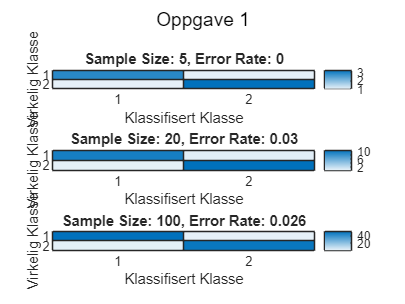

N_T = [5 20 100];
num_experiments = 5;
exp_set=x1; %Bytt mellom x1, x2 og x3

confusion_matrices = zeros(2, 2, num_experiments, numel(N_T));
error_rates = zeros(num_experiments, numel(N_T));
true_labels = [ones(1, N), 2 * ones(1, N)];

for exp_idx = 1:num_experiments
    for nt_idx = 1:numel(N_T)

        sample_indices = randperm(numel(exp_set), N_T(nt_idx));
        samples = exp_set(sample_indices);        

        predicted_labels = (abs(samples - m1) > abs(samples - m2)) + 1;
        
        confusion_matrix = confusionmat(true_labels(sample_indices), predicted_labels);
        confusion_matrices(:, :, exp_idx, nt_idx) = confusion_matrix;
        
        is_correct = (true_labels(sample_indices) == predicted_labels);
        error_rate = sum(~is_correct) / numel(is_correct);
        error_rates(exp_idx, nt_idx) = error_rate;
    end
end

avg_confusion_matrices = mean(confusion_matrices, 3);

avg_error_rates = mean(error_rates, 1);

figure;
sgtitle("Oppgave 1");
for nt_idx = 1:numel(N_T)
    avg_confusion_matrix = avg_confusion_matrices(:, :, nt_idx);
    avg_error_rate = avg_error_rates(nt_idx);

    subplot(numel(N_T), 1, nt_idx);
    heatmap(avg_confusion_matrix);
    title("Sample Size: " + N_T(nt_idx) + ", Error Rate: " + avg_error_rate);
    xlabel('Klassifisert Klasse');
    ylabel('Virkelig Klasse');
end

Oppgave 2

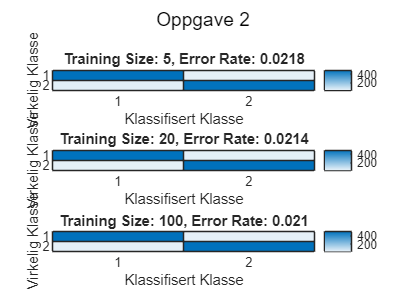

exp_set=x1; %Bytt mellom x1, x2 og x3
train_set1=exp_set(1:500); 
train_set2=exp_set(1001:1500);
test_set=[exp_set(501:1000) exp_set(1501:end)];
true_labels = [ones(1, 500), 2 * ones(1, 500)];

N_D=[5 20 100];
num_experiments = 5;

confusion_matrices = zeros(2, 2, num_experiments, numel(N_D));
error_rates = zeros(num_experiments, numel(N_D));

for exp_idx = 1:num_experiments
    for nd_idx = 1:numel(N_D)
        sample_indices = 1+(exp_idx-1)*N_D(nd_idx):exp_idx*N_D(nd_idx);

        mu1=mean(train_set1(sample_indices));
        mu2=mean(train_set2(sample_indices));

        predicted_labels = (abs(test_set - mu1) > abs(test_set - mu2)) + 1;
        
        confusion_matrix = confusionmat(true_labels, predicted_labels);
        confusion_matrices(:, :, exp_idx, nd_idx) = confusion_matrix;
        
        is_correct = (true_labels == predicted_labels);
        error_rate = sum(~is_correct) / numel(is_correct);
        error_rates(exp_idx, nd_idx) = error_rate;
    end
end

avg_confusion_matrices = mean(confusion_matrices, 3);

avg_error_rates = mean(error_rates, 1);

figure;
sgtitle("Oppgave 2");
for nd_idx = 1:numel(N_D)
    avg_confusion_matrix = avg_confusion_matrices(:, :, nd_idx);
    avg_error_rate = avg_error_rates(nd_idx);
 
    subplot(numel(N_D), 1, nd_idx);
    heatmap(avg_confusion_matrix);
    title("Training Size: " + N_D(nd_idx) + ", Error Rate: " + avg_error_rate);
    xlabel('Klassifisert Klasse');
    ylabel('Virkelig Klasse');
end

Oppgave 3

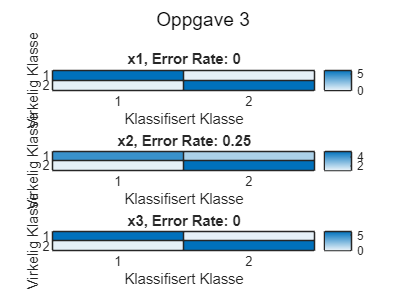

nSamples=6;
true_labels=[1 2];
error_rates=zeros(1, 3);
total_confusion_matrix=zeros(2,2,3);

for dataset_idx = 1:3
    if dataset_idx == 1
        test_set1 = x11(1:nSamples);
        test_set2 = x12(1:nSamples);
    elseif dataset_idx == 2
        test_set1 = x21(1:nSamples);
        test_set2 = x22(1:nSamples);
    else
        test_set1 = x31(1:nSamples);
        test_set2 = x32(1:nSamples);
    end
    
    confusion_matrix = zeros(2, 2);
    misclassifications = 0;

    for idx = 1:nSamples
        mu1 = mean(test_set1([1:idx-1, idx+1:end]));
        mu2 = mean(test_set2([1:idx-1, idx+1:end]));

        predicted_label1 = (abs(test_set1(idx)-mu1) > abs(test_set1(idx)-mu2)) + 1;
        predicted_label2 = (abs(test_set2(idx)-mu1) > abs(test_set2(idx)-mu2)) + 1;

        confusion_matrix = confusion_matrix + confusionmat(true_labels, [predicted_label1 predicted_label2]);

        if predicted_label1 ~= true_labels(1) || predicted_label2 ~= true_labels(2)
            misclassifications = misclassifications + 1;
        end
    end
    
    total_confusion_matrix(:,:,dataset_idx) = confusion_matrix; 
    error_rates(dataset_idx) = misclassifications / (2 * nSamples);
end

figure;
sgtitle("Oppgave 3");
for dataset_idx = 1:3
    subplot(3,1,dataset_idx);
    heatmap(total_confusion_matrix(:,:,dataset_idx));
    title("x"+dataset_idx+", Error Rate: "+error_rates(dataset_idx));
    xlabel('Klassifisert Klasse');
    ylabel('Virkelig Klasse');
end